# Using the SARB Data Connector

## 1. Introduction

Welcome to the tutorial on using the SARB Data Connector, an API connector designed to retrieve economic data from the South African Reserve Bank (SARB) web API. In this tutorial, we will walk you through the process of using the connector to access various types of data provided by the SARB. The connector provides convenient methods for retrieving data from SARB.

To do this we're doing to use the `ResBankEconData` class which is a MATLAB class designed to facilitate the retrieval of economic data from the South African Reserve Bank (SARB) web API. It provides methods and properties that enable users to access various types of economic data provided by SARB., make sure you have the SARB Data Connector class file available. 

This tutorial assumes you have a basic understanding of MATLAB or similar programming languages.

## 2. Getting Started

To begin using the SARB Data Connector, you need to have the ResBankEconData class available in your MATLAB environment. Ensure that you have the class file loaded and accessible.

First create an instance of the ResBankEconData class:

connector = ResBankEconData;

## 3. Retrieving Economic Data

The SARB Data Connector allows you to retrieve various types of economic data. The `retrieveData` method is used to fetch data from the SARB web API based on the specified data type.

Method signature: `outputTable = retrieveData(economicData)`

There are several types of economic data available to fetch using `retrieveData:`

- Home Page Rates: 'HomePageRates':

        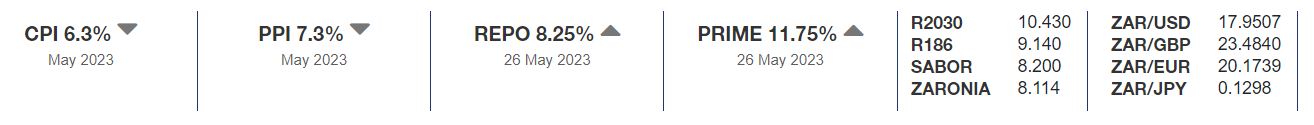

- Current Market Rates: 'CurrentMarketRates'

- CPD Rates: 'CPDRates'

- Daily Historical Exchange Rates: 'HistoricalExchangeRatesDaily'

- Monthly HistoricalExchangeRates: 'HistoricalExchangeRatesMonthly'

- Selected Data: 'ReleaseOfSelectedData'

- Real Sector Data: 'RealSectorData'

- Fiscal Sector Data: 'FiscalSectorData'

- Financial Sector Data: 'FinancialSectorData'

- External Sector Data: 'ExternalSectorData'

- Population Data: 'PopulationData'

economicData = 'CurrentMarketRates';
data = connector.retrieveData(economicData)

data = 24×9 table
                       Name                        SectionId           SectionName           TimeseriesCode         Date         Value    UpDown    FormatNumber      FormatDate  
    ___________________________________________    __________    ________________________    ______________    ______________    _____    ______    ____________    ______________

    {'Repo rate'                              }    {'CMRMMR'}    {'Money Market Rates'  }     {'MMSD008A'}     {'2023-07-18'}     8.25       0       {'0.00' }      {'yyyy-MM-dd'}
    {'Sabor'                                  }    {'CMRMMR'}    {'Money Market Rates'  }     {'MMSD719A'}     {'2023-07-17'}      8.2    

The `retrieveData` method retrieves the specified data type from the SARB web API and returns the data as a table.

## 4. Retrieving Time Series Data

The SARB Data Connector also provides a method to fetch time series data within a specified date range. The `getTimeSeries` method allows you to retrieve time series data based on the provided time series code, start date, and end date.

Method signature: `timeSeries = getTimeSeries(timeSeriesCode, startDate, endDate)`

This method takes in the following parameters:

- `timeSeriesCode`: A string representing the code for the time series to retrieve data for. You can obtain this from the table you retrieved in the previous section

- `startDate`: A string specifying the start date for the time series in the format 'yyyy-MM-dd'.

- `endDate`: A string specifying the end date for the time series in the format 'yyyy-MM-dd'.

Using data from the real sector as an example we're going to fetch time series data for Agriculture, forestry and fishing for the last 10 years, which has the time series code: `NRI6631L`

% Retrieve time series data for the specified code and date range
timeSeriesData = connector.getTimeSeries('NRI6631L', '2012-01-01', '2022-12-31');
disp(timeSeriesData);

            Period                           Timeseries                                                                      Description                                                           Value       FormatNumber    FormatDate
    _______________________    ______________________________________    ____________________________________________________________________________________________________________________    __________    ____________    __________

    {'2022-12-31T00:00:00'}    {'Agriculture, forestry and fishing '}    {'Gross value added at basic prices of agriculture, forestry and fishing <br/> Current prices. Seasonally adjusted'}    2.0442e+05       {'0'}        {'Qq/yy'} 
    {'2022-09-30T00:00:00'}    {'Agriculture, forestry and fishing '}    {'Gross value added 

The `getTimeSeries` method retrieves the time series data from the SARB web API and returns the data as a table.

## 5. Retrieving Selected Data from Statistics Release

The SARB Data Connector enables you to fetch specific data from the statistics release tables. The `sectionData` method retrieves the selected data for the specified code from the SARB web API and returns the data as a table. If called without any inputs, it displays a table presenting the available data types.

Method signature: `selectedData = sectionData(DataType)`

DataType: (Optional) A string representing the data type code to retrieve data for. If not provided, the available data types will be displayed, and you can input the code interactively.

Calling the method without an input:

selectData = connector.sectionData();

     DataType                       Indicator                       LatestDate        LastPeriod  
    __________    _____________________________________________    _____________    ______________

    {'MRDMA' }    {'Money and banking'                        }    {'May, 2023'}    {'2023-07-12'}
    {'MRDBM' }    {'Banks and mutual banks'                   }    {'May, 2023'}    {'2023-06-30'}
    {'MRDIE' }    {'International economic data'              }    {'May, 2023'}    {'2023-07-07'}
    {'MRDCM' }    {'Capital market'                           }    {'May, 2023'}    {'2023-06-30'}
    {'MRDFG' }    {'National government finance'              }    {'May, 2023'}    {'2023-06-30'}
    {'MRDEI' }    {'Economic indicators (seasonally adjusted)'}    {'Jun, 2023'}    {'2023-07-18'}
    {'MRGMA' }    {'Money and banking graphs'                 }    {'Ma

From this table you can get the code for the `DataType` you want to use. Input the DataType into the prompt that appears in the command window(*Note: Inputs are not case sensitive*)

Calling the method with an input:

selectDataInput = connector.sectionData('MRDBM');

By utilizing the `sectionData` method, you can easily access specific data from the SARB statistics release tables, enabling you to analyze and explore the economic indicators of interest. 

Once you have retrieved the table you can get the time series code from the TsCode column and use the getTimeSeries method to obtain the time series data

## 6. Conclusion

You have completed the tutorial on using the SARB Data Connector to access economic data from the South African Reserve Bank web API. By following the steps outlined in this tutorial, you have learned how to retrieve various types of economic data. 

Once you have the data within your MATLAB environment, you have access to a feature-rich environment that empowers you to perform a wide range of analysis, modeling, research, and more. 

This tutorial was only an overview, there is a vast amount of data at your disposal - we encourage you to explore the SARB Data Connector further, experiment with different data types, and unlock the full potential of MATLAB's tools and functionalities. Embrace the power of data-driven analysis and modeling to deepen your understanding of the South African economy and contribute to meaningful economic research and decision-making processes.